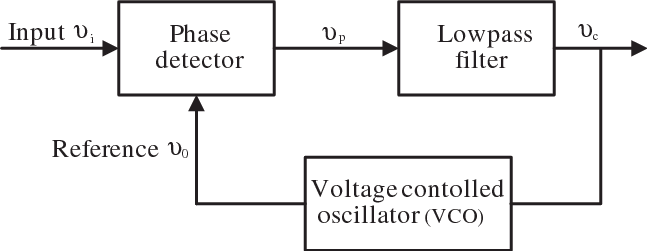

[1] F. D. Freijedo, J. Doval-Gandoy, O. Lopez and J. Cabaleiro, "Robust phase locked loops optimized for DSP implementation in power quality applications,"

**Input Waveform **(Considering a normalize & 12 Bits)

% clear all
tsample=1/5e3; %Q0.32 fi(1/10e3,0,32,32)
tsim = 17.5*1/50; %10 cycles 
t=0:tsample:tsim;


**Notch Filter Design **

%                s^2+wo^2                    z-1 
% H(s) = -----------------------------  s=-----------
%             s^2+s*wo/q+wo^2               tsample

%A0=fi((-2+tsample*wo/q),1,32,30);A1=fi((1+wo*wo*tsample*tsample-tsample*wo/q),1,32,31);A3=fi(2,1,32,29);
%A4=fi((1+wo*wo*tsample*tsample),1,32,30);
%NF(k)=-NF(k-1)*A0-NF(k-2)*A1+PD(k)-A3*PD(k-1)+A4*PD(k-2)

wo = 2*pi*50*2;    %Q12.20 fi(2*pi*100,1,32,20)
BW = 2*pi*(1000);
q = wo/BW; %Q1.32 fi(100/(150-65),0,32,31)
NF_s=tf([1 0 wo*wo],[1 wo/q wo*wo]);
NF_z=c2d(NF_s,1/50e3,'zoh');

**Figures**

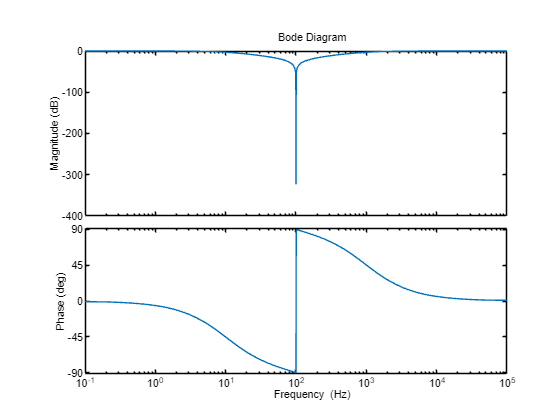

P = bodeoptions; 
P.FreqUnits = 'Hz'; 
bodeplot(NF_s,P); 

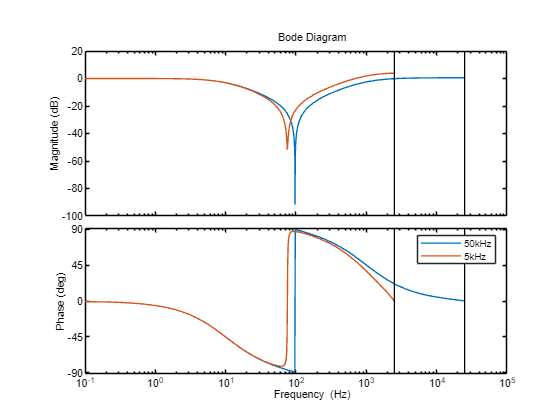

NF_z2=c2d(NF_s,1/5e3,'zoh');
bodeplot(NF_z,NF_z2,P); 
legend('50kHz','5kHz')

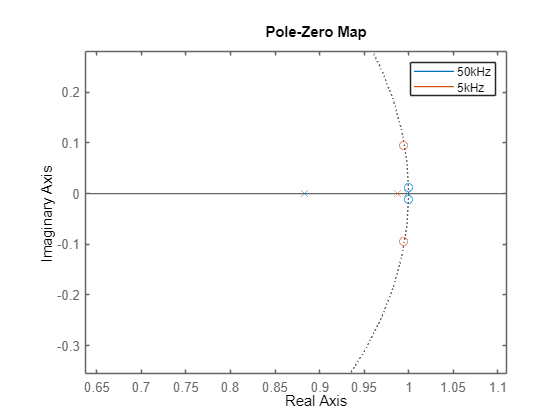

figure(66)
h2 = pzplot(NF_z,NF_z2); %With a 50kHz sampling freq the nf is tending to more instability.
p = getoptions(h2);
p.XLim = {[0.636834, 1.11026]};
p.YLim = {[-0.356221, 0.281674]};
setoptions(h2,p);
legend('50kHz','5kHz')

**PI (LF) Desgin**

%            s*kpp+kii
% PI(s) = ----------------
%                s

%           2*Kp+Tsample*Ki+z^-1*(Tsample*ki-2*Kp)          
% PI(z) = --------------------------------
%                     2-2*z^-1

%B0=fi((kpp+(.5*tsample*kii)),1,32,23);B1=fi((-kpp+(.5*tsample*kii)),1,32,23);
%PIout(k)=PIout(k-1)+NFout(k)*B0+NFout(k-1)*B1;

kpp=350;
kii=20e4;
h_g_s=tf([kpp kii],[1 0]);
h_g_z=tf([kpp+.5*1/50e3*kii (.5*1/50e3*kii-kpp)],[1 -1],1/50e3);
h_g_z2=tf([kpp+.5*1/5e3*kii (.5*1/5e3*kii-kpp)],[1 -1],1/5e3);

**Figures**

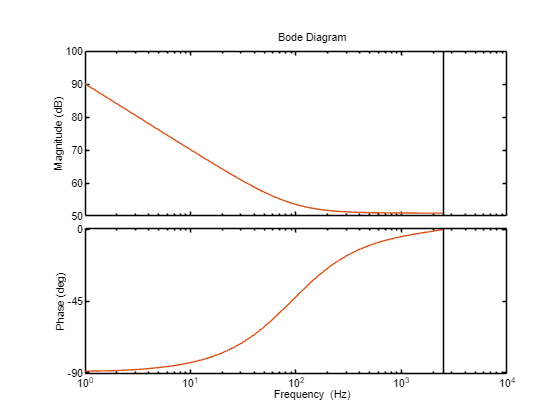

bodeplot(h_g_z2,h_g_z2,P)

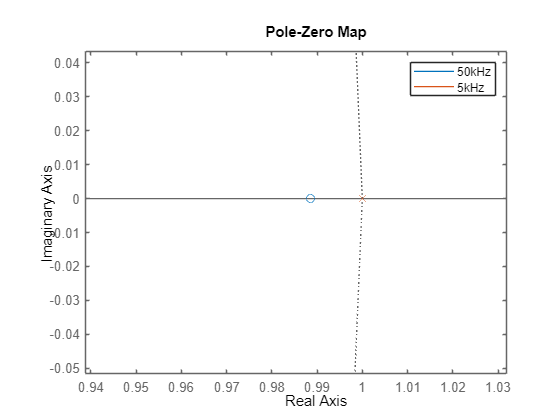

h = pzplot(h_g_z,h_g_z2);
p2 = getoptions(h);
p2.XLim = {[0.938716, 1.03198]};
p2.YLim = {[-0.0516891, 0.043478]};
setoptions(h,p2);
legend('50kHz','5kHz')

**Filter Overall**

% wo = 2*pi*50*2;    %Q12.20 fi(2*pi*100,1,32,20)
% BW = 2*pi*(320);
% q = wo/BW; %Q1.32 fi(100/(150-65),0,32,31)
% NF_s=tf([1 0 wo*wo],[1 wo/q wo*wo]);
% kpp=255;
% kii=25e3;
% h_g_s=tf([kpp kii],[1 0]);
% FO=NF_s*h_g_s
% pzmap(2500*NF_s*h_g_s)
% bodeplot(FO,P)

**Simulation**

% Init States
% ws=fi((2*pi*50),1,32,22);%(2*pi*50);
% cos_th=fi(zeros(length(t),1),1,32,31);%zeros(length(t),1); 
% cos_th(2)=fi(.99,1,32,31); %.99
% sin_th=fi(zeros(length(t),1),1,32,31);
% PDout=fi(zeros(length(t),1),1,32,31);%zeros(length(t),1);
% NFout=fi(zeros(length(t),1),1,32,31);%zeros(length(t),1);
% PIout=fi(zeros(length(t),1),1,32,24);%zeros(length(t),1);
% phase_th=fi(zeros(length(t),1),1,32,29);%zeros(length(t),1);
% pi32=fi(pi,1,32,29);
% wout=ws;
% 
% A0=fi((-2+tsample*wo/q),1,32,30);A1=fi((1+wo*wo*tsample*tsample-tsample*wo/q),1,32,31);A3=fi(2,1,32,29);
% A4=fi((1+wo*wo*tsample*tsample),1,32,30);
% 
% B0=fi((kpp+(.5*tsample*kii)),1,32,23);B1=fi((-kpp+(.5*tsample*kii)),1,32,23);
% 
% Input Waveform
% sin_in = fi(sin(2*pi*50*t+pi)+sin(2*pi*60*t*3+pi)*.02,1,12,11);  % 60Hz with third harmonic
% t1=0:tsample:tsim/2;
% t1=tsim/2:tsample:tsim;
% sin_in=  [sin(2*pi*60*t1(1:length(t1-1))+pi) sin(2*pi*60*t2+pi)];
% sin_in=fi(sin_in,1,12,11);
% plot(t,sin_in)
% 
% For this case the PLL is config for operating a Fs of the GRid of 50Hz,
% but the input is a 60Hz with third harmonic and with pi of phase difference one of the worse cases.
% 
% for k=3:(length(t))
%     PD block %Q1.15  
% 
%         PDout(k) =  fi(sin_in(k-1)*cos_th(k-1),1,32,31);
% 
%     NF
% 
%         NFout(k)=-NFout(k-1)*A0-NFout(k-2)*A1+PDout(k)-A3*PDout(k-1)+A4*PDout(k-2);
% 
%         the idea is to be able to move the fc of the nf to the actual detected fs of the grid   
%         A1=fi((1+(wout*2*wout*2*tsample*tsample)-(tsample*BW)),1,32,31);
%         A4=fi((1+wout*2*wout*2*tsample*tsample),1,32,30);
% 
%     PI controller
%           PIout(k)=PIout(k-1)+NFout(k)*B0+NFout(k-1)*B1; 
% 
%     DCO
%         wout=PIout(k)+ws;
% 
%         Sin is for showing the overlaping w the input 
%         sin_th(k)=sin_th(k-1)+(cos_th(k-1)*wout*fi(tsample,1,32,43));%Sin(t+dt)=sin(t)+cos(t)*dt
%         cos_th(k)=cos_th(k-1)-(sin_th(k-1)*wout*fi(tsample,1,32,43));
% 
%         phase_th(k)=phase_th(k-1)+wout*fi(tsample,1,32,43);
% 
%         if sin_th(k-1)>=0 && sin_th(k)<=0
%             phase_th(k)=-pi32; %zero crossing reseting phase angle
%         end
% 
% end

**Figures**

% close all
% figure(1)
% plot(t,phase_th,t,sin_th,t,sin_in(1:end-1))
% plot(t,phase_th,t,sin_th,t,sin_in)
% legend('Angle','SinOut','SinIn')
% figure(2)
% plot(t,PDout)
% legend('Phase Detector')
% figure(3)
% plot(t,NFout)
% legend('Error NFout')

% figure(4)
% plot(t,PIout)
% legend('Control Effort')